g = @(x) (exp(-x));
tol = 10.^-10;
N = 100;
x0 = 0.75;
[c, n, err] = fixed_point_iteration(g, x0, tol, N)

c = 0.5671

n = 100

err = 0.2776



g1 = @(x) (1/2).*(x + (5/x));  %@(x) 1 / (1 + x);
tol = 1e-5; N1 = 100;
x01 = 2; 
[c1, n1, err1] = fixed_point_iteration(g1, x01, tol, N1)

c1 = 2.2361

n1 = 100

err1 = 0.2500

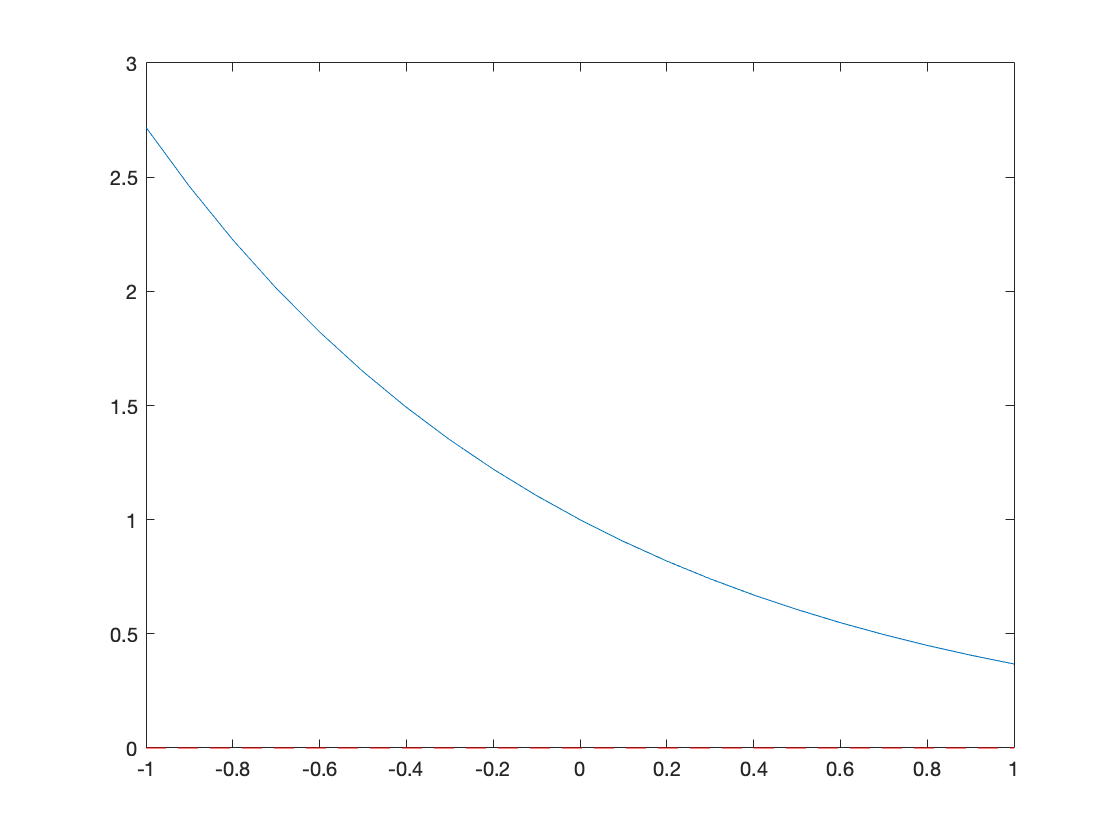


plot([-1:0.1:1],g([-1:0.1:1]),[-1:0.1:1], 0 *[-1:0.1:1], "r--")

function [c, n, err] = fixed_point_iteration(g, x0, tol, N)
n = 0;
c = g(x0);
err = abs(c - x0);
while n < N
    c = g(x0);
    n = n + 1;
    x0 = c;
end
end

  
